步骤 1：生成实验设计

% 定义因子水平
factor_levels = {
    [1, 2],      % A: 2 levels
    [1, 2, 3],   % B: 3 levels
    [1, 2],      % C: 2 levels
    [1, 2],      % D: 2 levels
    [1, 2, 3],   % E: 3 levels
    [1, 2, 3]    % F: 3 levels
};

% 生成全因子设计
[comb_A, comb_B, comb_C, comb_D, comb_E, comb_F] = ndgrid(factor_levels{:});
full_factorial = [comb_A(:), comb_B(:), comb_C(:), comb_D(:), comb_E(:), comb_F(:)];
num_experiments = size(full_factorial, 1);

% 假设有 9 个响应变量
num_responses = 9;
response = zeros(num_experiments, num_responses);

% 模拟响应变量（用随机数据占位，可以替换为真实数据）
for r = 1:num_responses
    response(:, r) = 10 * full_factorial(:, 1) + ...
                     5  * full_factorial(:, 2) + ...
                     3  * full_factorial(:, 3) + ...
                     2  * full_factorial(:, 4) + ...
                     8  * full_factorial(:, 5) + ...
                     6  * full_factorial(:, 6) + ...
                     randn(num_experiments, 1) * r; % 加入随机噪声
end

步骤 2：线性模型拟合并计算残差

Response_1 的残差通过正态性检验（p = 0.74742）。


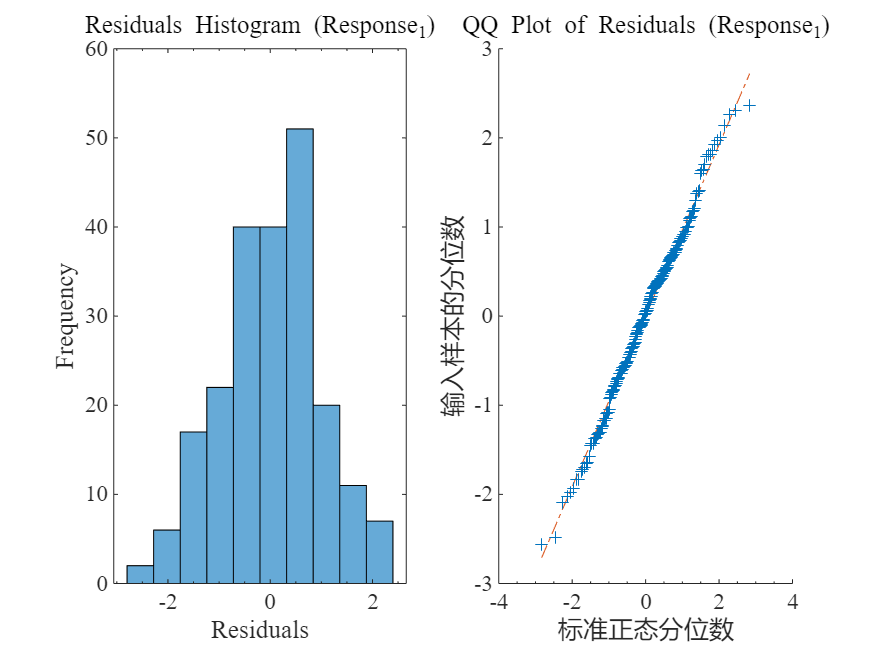

Response_2 的残差通过正态性检验（p = 0.77212）。


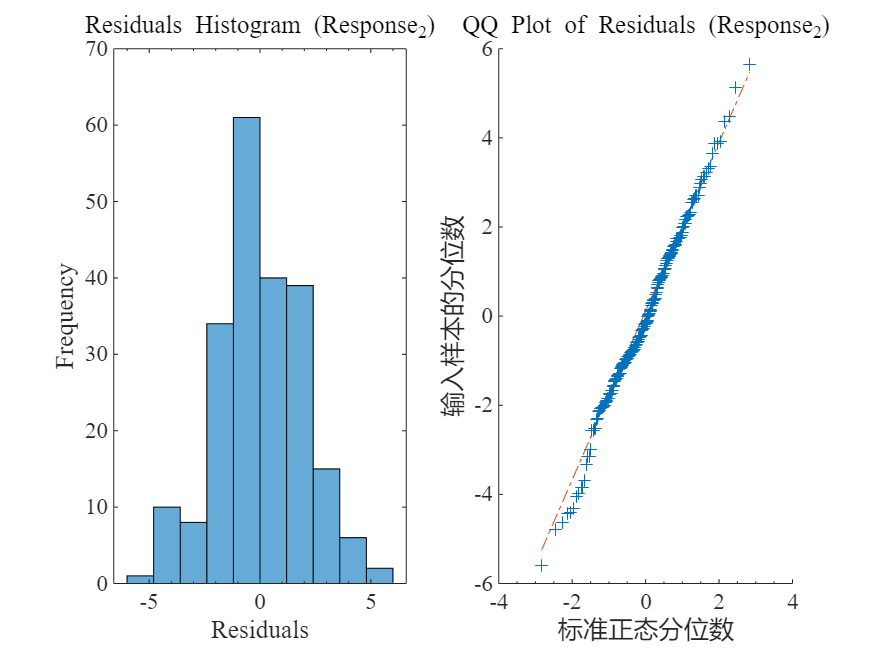

Response_3 的残差通过正态性检验（p = 0.85976）。


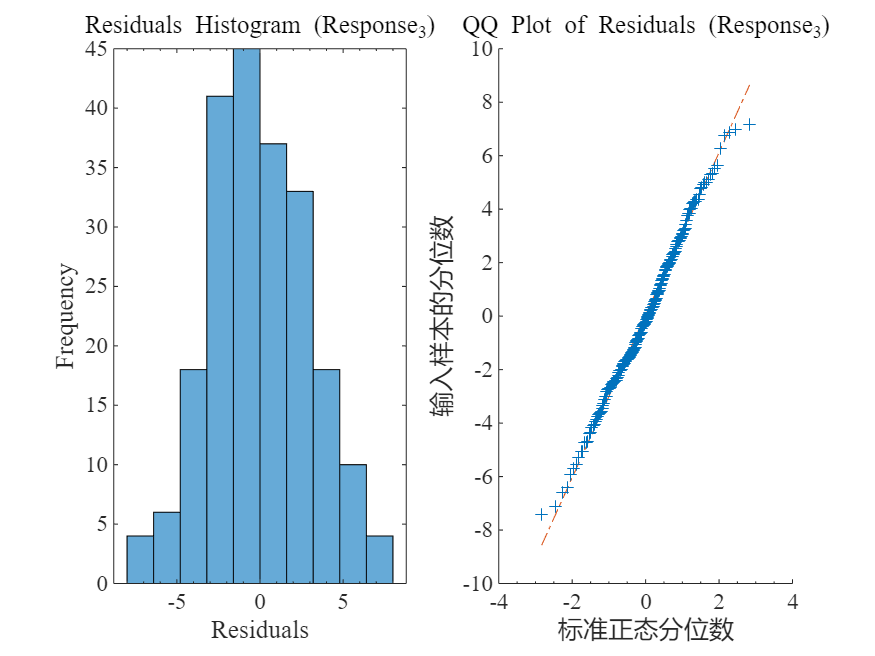

Response_4 的残差通过正态性检验（p = 0.98294）。


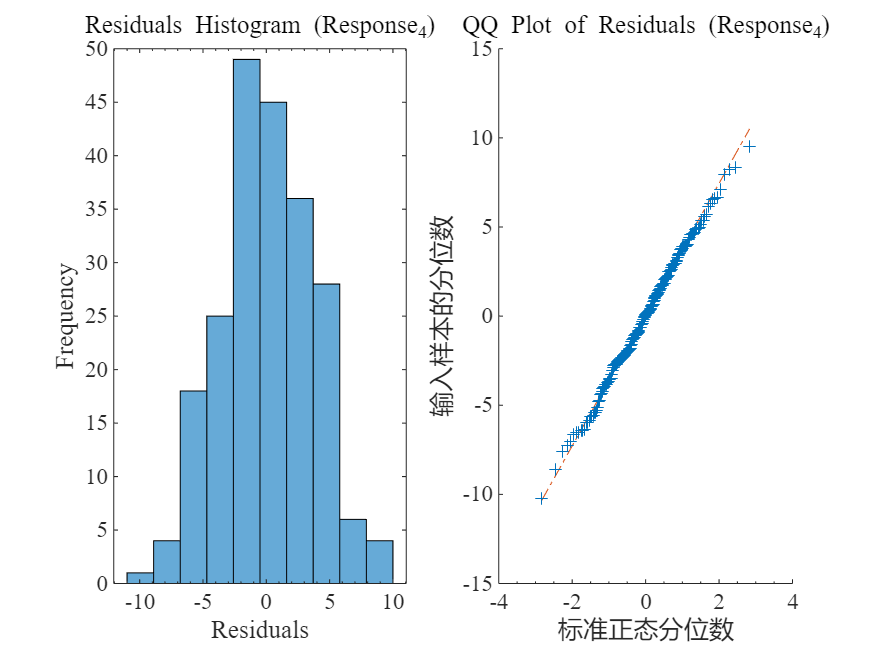

Response_5 的残差通过正态性检验（p = 0.73113）。


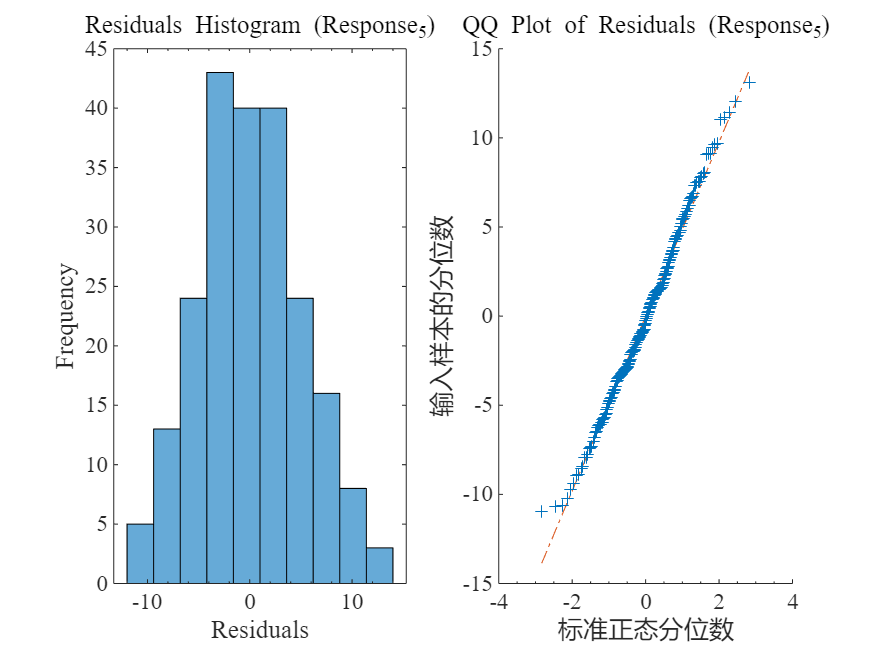

Response_6 的残差通过正态性检验（p = 0.63224）。


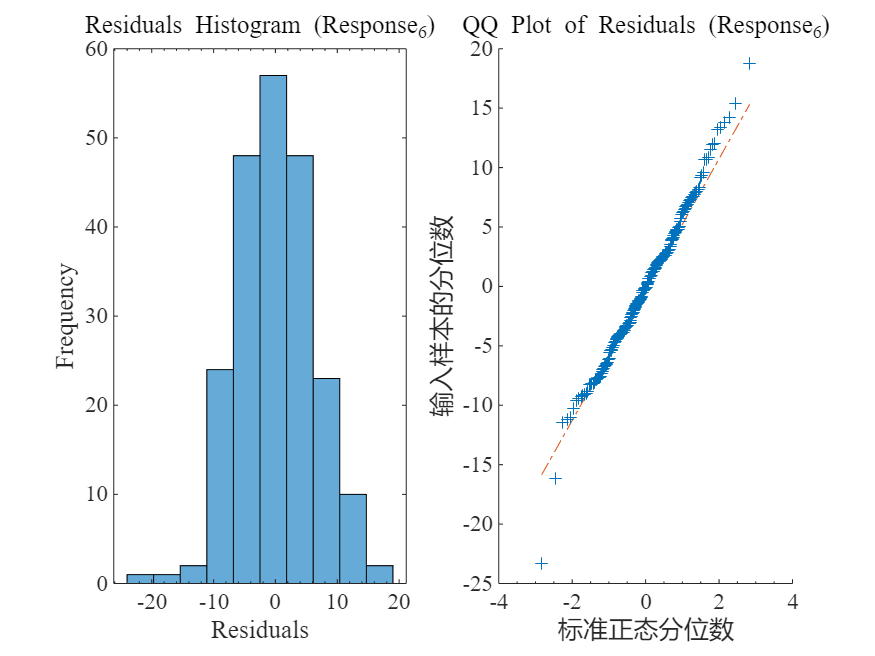

Response_7 的残差通过正态性检验（p = 0.82742）。


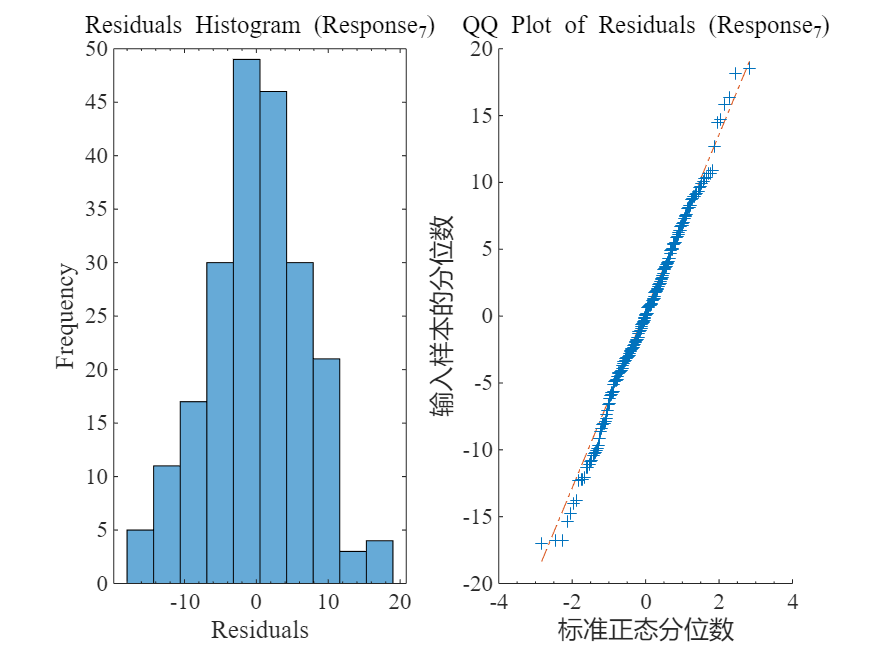

Response_8 的残差通过正态性检验（p = 0.99948）。


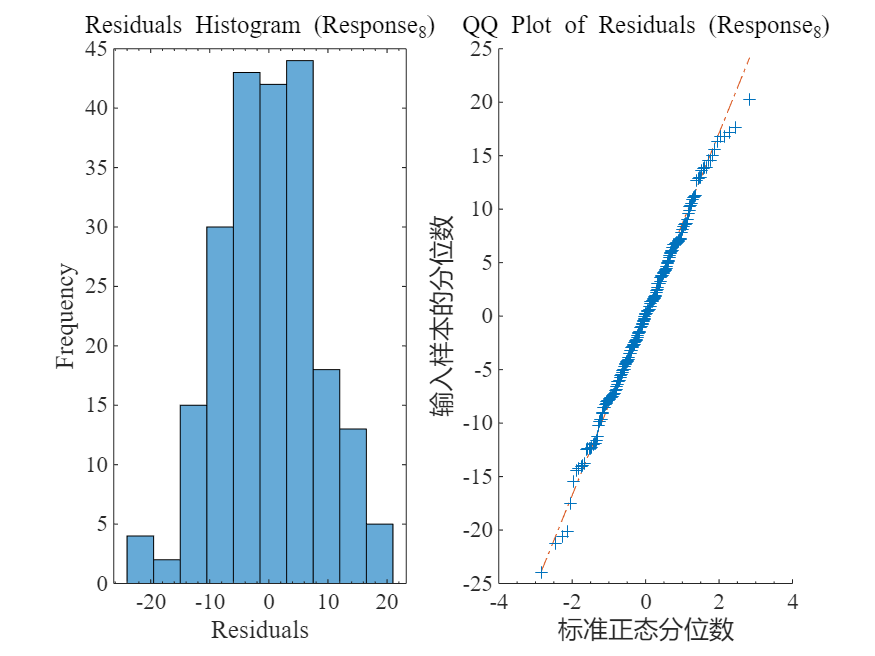

Response_9 的残差通过正态性检验（p = 0.88346）。


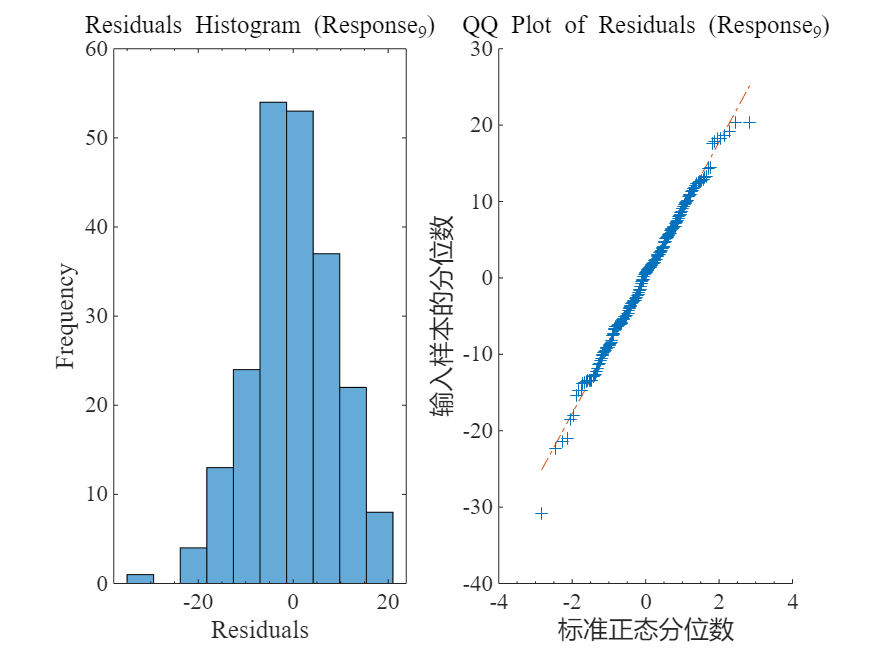

% 添加常数项到设计矩阵
X = [ones(num_experiments, 1), full_factorial]; % 包含常数项

for r = 1:num_responses
    % 当前响应变量
    current_response = response(:, r);
    
    % 拟合线性模型
    b = X \ current_response; % 最小二乘法估计系数
    predicted_response = X * b; % 预测值
    
    % 计算残差
    residuals = current_response - predicted_response;
    
    % 对残差进行正态性检验
    [h, p] = kstest((residuals - mean(residuals)) / std(residuals)); % Kolmogorov-Smirnov 检验
    
    % 显示正态性检验结果
    if h == 0
        disp(['Response_', num2str(r), ' 的残差通过正态性检验（p = ', num2str(p), '）。']);
    else
        disp(['Response_', num2str(r), ' 的残差未通过正态性检验（p = ', num2str(p), '）。']);
    end
    
    % 绘制残差的直方图和 QQ 图
    figure;
    subplot(1, 2, 1);
    histogram(residuals, 10);
    title(['Residuals Histogram (Response_', num2str(r), ')']);
    xlabel('Residuals');
    ylabel('Frequency');
    
    subplot(1, 2, 2);
    qqplot(residuals);
    title(['QQ Plot of Residuals (Response_', num2str(r), ')']);
end